# Simulating Pendulum Model 

## Problem

**Given: **Pendulum model

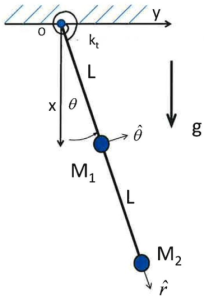

where $\theta(t)$is the solution to the ODE model.

**Challenge: **

Simulate the pendulum motion for a range of length values $L = [0.1, 0.3] \, \text{m}$, to investigate the affect of the length parameter on the pendulum motion.

## Original, Non-Parameterized, Solution

Formulate the second-order equation of motion as a system of two first-order equations by introducing a new variable for angular velocity, $\omega(t) = \dot{\theta}(t)$.

The state vector is


$$\: \mathbf{x}(t) = \left\{ \matrix{\theta(t) \cr \omega(t) } \right\}$$


(We can define this with the variables in any order.)


$$ \left\{ \matrix{\dot{\theta}(t) \cr \dot{\omega}(t) } \right\} = 
\left\{ \matrix{ \omega \cr \frac{-1}{5 m L^2} (k_t \, \theta + 3 m g L \sin{\theta}}\right\}$$


If the mass (and all other parameters) is **fixed**, we can include the value within the rate function:

function dxdt = p_rate(t, xx)
    m = 0.36; % kg
    kt = 0.89; % Nm/rad
    L = 0.21; % m
    g = 9.81; % m/s^2
    dxdt = [ xx(2);
        -1/(5*m*L^2)*(kt*xx(1) + 3*m*g*L*sin(xx(1)))];
end

And simulate by finding the ode45 solution for non-linear dynamics

x0 = [1 0];
tspan = [0 2];
[tt, X] = ode45(@p_rate, tspan, x0);
figure;
clf;
plot(tt,X(:,1),'LineWidth',2)
xlabel("Time (s)")
ylabel("\theta (rad)")
grid('on')

With this framework **we cannot change the length paramete without editting the **`p_rate`** function.**

### Step 1: Parameterize the rate function

Write a new rate function that includes the parameter we want to change.   Adding **L** to the input arguments.

function dxdt = p_rate_parameterized(t, xx, L)
    m = 0.36; % kg
    kt = 0.89; % Nm/rad
    L = L; % m
    g = 9.81; % m/s^2
    dxdt = [ xx(2);
        -1/(5*m*L^2)*(kt*xx(1) + 3*m*g*L*sin(xx(1)))];
end

### Step 2: Iterate through parameter space

ll = linspace(0.15, 0.25, 5);
figure; clf;
for ii = 1:length(ll)
    L = ll(ii);


###         Step 3: Within the loop, define a new rate function, compatible with ode45, that uses the new model parameter

    new_rate_function_handle = @(t, xx) p_rate_parameterized(t, xx, L);

###         Step 4: Solve this new model

    [tt, X] = ode45(new_rate_function_handle, tspan, x0);

and plot

    plot(tt, X(:,1), 'DisplayName', sprintf('L = %.2f m', L));
    hold on
end

xlabel("Time (s)")
ylabel("\theta (rad)")
grid('on')
legend()
